# Reading in model run cage information

This guide explains how to read in information about cage layouts

## Reading in cages associated with a model run

Assuming a model run is instantiated, reading in the associated cage information is straightforward.

run = project.solidsRuns.first;

site = run.cages

site =   2 Site array with properties:

    cageGroups: {[4 Depomod.Layout.Cage.Group]  [4 Depomod.Layout.Cage.Group]}
          path: 'C:\newdepomod_projects\bay_of_fish\depomod\cages\bay_of_fish-1.depomodcagesxml'

This returns a `Depomod.Layout.Site` object.

## Using the cages object

The Matlab cages representation can be used in a variety of ways.

The site has two cage groups, each with four cages

site.cageGroups

ans = 1×2 cell array
    {4 Depomod.Layout.Cage.Group}    {4 Depomod.Layout.Cage.Group}

site.size

ans =      2

We can return the total number of cages

site.sizeCages

ans =      8

and the total cage area and volume

site.cageArea % m2

ans =           6369.80278655024

site.cageVolume % m3

ans =           76437.6334386029

We can return a variety of** geospatial information**. For example, the mean cage position (in easting/northings)

[e,n] = site.meanCagePosition

e =           350331.829779636

n =           1069062.49294748

The position of the corners of the site

corners = site.corners

corners =           350421.067926405          1069147.01907142
          350209.304110391          1069052.73007305
          350242.593108762          1068977.96625704
          350454.356924777          1069072.25525541


The direction of the site major axis

site.majorAxis % relative to north

ans =           245.998719034112

and the directions orthogonal to the major axis

site.orthogonalBearings

ans =           245.998719034112          335.998719034112           65.998719034112          155.998719034112


## Navigating individual cages

Individual cages can be drilled into.

cage = site.cageGroups{1}.cages{1}

cage =   Circle with properties:

               x: 350413
               y: 1069126
          length: 31.84
           width: 31.84
          height: 12
           depth: 6
        inputsId: '4c97b36c-bd67-44db-bfe7-15d6b3b298d2'
      proportion: 0.125
    inProduction: 1

This is a Matlab representation of an individual cage, corresponding to the information in the NewDepomod cages file. This cage is a circular cage as indicated by the type of object.

class(cage)

ans = 'Depomod.Layout.Cage.Circle'

We can query the individual attributes:

cage.x % easting

ans =       350413

cage.y % northing

ans =      1069126

cage.height % m

ans =     12

cage.width % m (diameter)

ans =                      31.84

cage.proportion

ans =                      0.125

and also make use of methods which can produce additional information.

cage.area % m2

ans =            796.22534831878

cage.volume % m3

ans =           9554.70417982536

ans =           100.028310090299

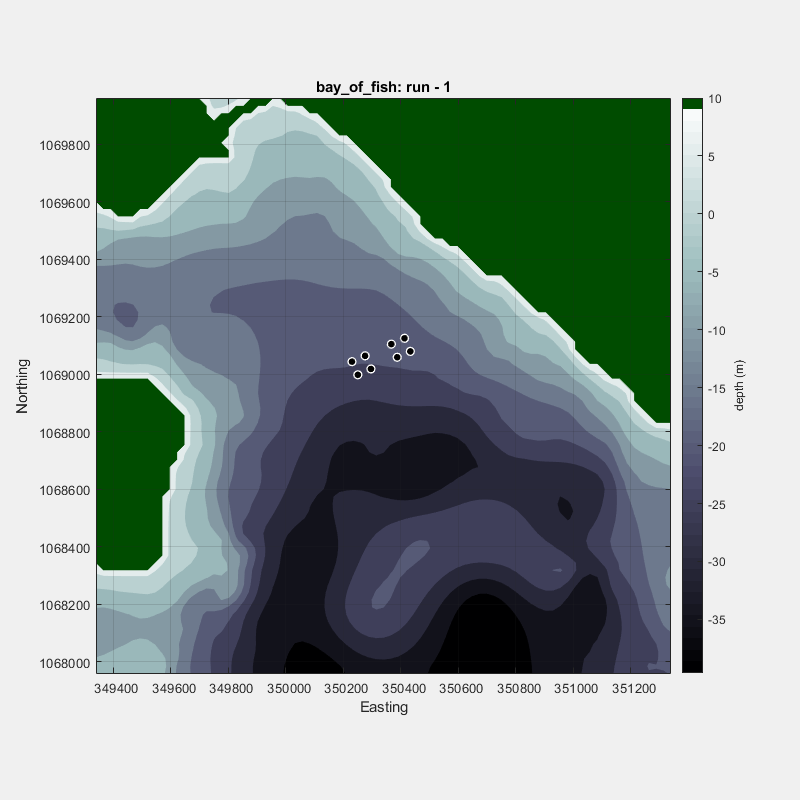

ans =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 0 600 600]
       Units: 'points'

  Show all properties

cages = 1×8 cell array
    {1×1 Depomod.Layout.Cage.Circle}    {1×1 Depomod.Layout.Cage.Circle}    {1×1 Depomod.Layout.Cage.Circle}    {1×1 Depomod.Layout.Cage.Circle}    {1×1 Depomod.Layout.Cage.Circle}    {1×1 Depomod.Layout.Cage.Circle}    {1×1 Depomod.Layout.Cage.Circle}    {1×1 Depomod.Layout.Cage.Circle}

ans = 8×10 cell array
    {[1]}    {[          350413]}    {[         1069126]}    {[31.84]}    {[31.84]}    {[12]}    {[6]}    {'4c97b36c-bd67-44db-bfe7-15d6b3b298d2'}    {[0.125]}    {[1]}
    {[2]}    {[350367.322727118]}    {[1069105.66316785]}    {[31.84]}    {[31.84]}    {[12]}    {[6]}    {'4c97b36c-bd67-44db-bfe7-15d6b3b298d2'}    {[0.125]}    {[1]}
    {[3]}    {[350433.336832154]}    {[1069080.32272712]}    {[31.84]}    {[31.84]}    {[12]}    {[6]}    {'4c97b36c-bd67-44db-bfe7-15d6b3b298d2'}    {[0.125]}    {[1]}
    {[4]}    {[350387.659559272]}    {[1069059.98589496]}    {[31.84]}    {[31.84]}    {[12]}    {[6]}    {'4c97b36c-bd67-44db-bfe7-15d6b3b298d2'}    {[0.125]}    {[1]}
    {[5]}    {[          350276]}    {[         1069065]}    {[31.84]}    {[31.84]}    {[12]}    {[6]}    {'4c97b36c-bd67-44db-bfe7-15d6b3b298d2'}    {[0.125]}    {[1]}
    {[6]}    {[350230.322727118]}    {[1069044.66316785]}    {[31.84]}    {[31.84]}    {[12]}    {[6]}    {'4c97b36c-bd67-44db-bfe7-1

cage.perimeter % m (circumference)

## Reading in cages directly from a cage file

Cages can also be read outside of the context of a specific run or even whole project, by simply passing in the full file path.

filepath = 'C:\newdepomod_projects\bay_of_fish\depomod\cages\bay_of_fish-1.depomodcagesxml';

site = Depomod.Layout.Site.fromXMLFile(filepath)

site =   2 Site array with properties:

    cageGroups: {[4 Depomod.Layout.Cage.Group]  [4 Depomod.Layout.Cage.Group]}
          path: 'C:\newdepomod_projects\bay_of_fish\depomod\cages\bay_of_fish-1.depomodcagesxml'

In this case the same object is instantiated. 